# **测试导航滤波器**

clear
clc

## 仿真时间

T = 200;        % 总时间，s
dt = 0.01;      % 时间间隔，s
n = T / dt;     % 总仿真点数
t = (1:n)'*dt;  % 时间序列（列向量）

## 惯性器件指标

sigma_gyro = 0.15;             % 陀螺仪噪声标准差，deg/s
sigma_acc = 1.5e-3;            % 加速度计噪声标准差，g
bias_gyro = [0.2, 0, 0.6] *1;  % 陀螺仪常值零偏，deg/s
bias_acc = [1, 0, 2]*1e-3 *1;  % 加速度计常值零偏，g

## 接收机参数

sigma_rho = 3;            % 伪距测量噪声标准差，m
sigma_rhodot = 0.1;       % 伪距率测量噪声标准差，m/s
sigma_dphase = 0.004;     % 相位差测量噪声标准差，circ
dtr = 1e-8;               % 初始钟差，s
dtv = 3e-9;               % 初始钟频差，s/s
dpath = 0.2;              % 双天线路径差，circ
c = 299792458;            % 光速，m/s
lamda = c / 1575.42e6;    % 波长，m

## 接收机位置

lat = 46;      % 纬度，deg
lon = 126;     % 经度，deg
h = 200;       % 高度，m

## 基线

bl_psi = 50;       % 基线航向角，deg
bl_theta = 00;     % 基线俯仰角，deg
bl_gamma = 00;     % 基线滚转角，deg
bl_length = 1.3;   % 基线长度，m

## 卫星位置

% 第一列为方位角，第二列为高度角，deg
sv_info = [  0, 45;
            23, 28;
            58, 80;
           100, 49;
           146, 34;
           186, 78;
           213, 43;
           255, 15;
           310, 20];
rho = 20000000; % 卫星到接收机的距离，m

% figure
% polarscatter(sv_info(:,1)/180*pi, sv_info(:,2), ...
%              100, 'MarkerEdgeColor','g', 'MarkerFaceColor','y')
% ax = gca;
% ax.RLim = [0 90];
% ax.RDir = 'reverse';
% ax.ThetaDir = 'clockwise';
% ax.RTick = [0 15 30 45 60 75 90];

## 仿真惯性器件输出

Cnb = angle2dcm(bl_psi/180*pi, ...
                bl_theta/180*pi, ...
                bl_gamma/180*pi);
acc = (Cnb*[0;0;-1])'; % 真实加速度，g
imu = zeros(n,6);
imu(:,1:3) = ones(n,1)*bias_gyro + ...
             randn(n,3)*sigma_gyro; % 陀螺仪输出，零偏+噪声，deg/s
imu(:,4:6) = ones(n,1)*acc + ...
             ones(n,1)*bias_acc + ...
             randn(n,3)*sigma_acc;  % 加速度计输出，真值+零偏+噪声，g

## 计算卫星位置、速度和相位差

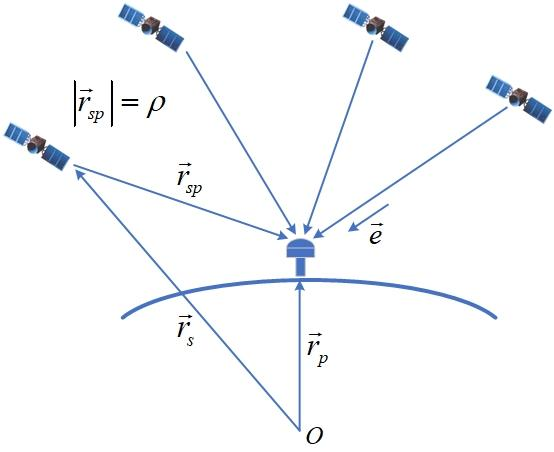

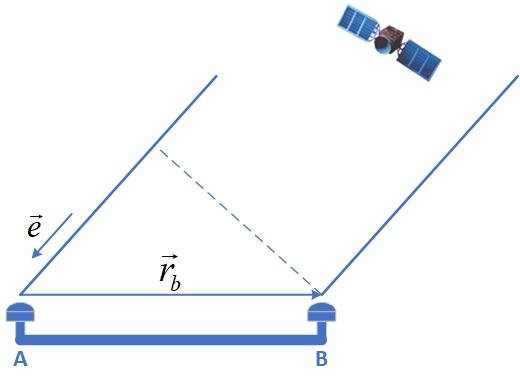


$$\delta \varphi =\varphi_A -\varphi_B =\frac{\overrightarrow{r_b } \cdot \overrightarrow{e} }{\lambda }$$


svN = size(sv_info,1); % 卫星个数
sv_real = zeros(svN,9); % 存储无误差卫星量测，[x,y,z, rho, vx,vy,vz, rhodot, dpahse]
Cen = dcmecef2ned(lat, lon);
rp = lla2ecef([lat, lon, h]); % 接收机位置矢量（ecef，行向量）
rb = [ cosd(bl_theta)*cosd(bl_psi), ...
       cosd(bl_theta)*sind(bl_psi), ...
      -sind(bl_theta)] * bl_length; % 基线位置矢量（地理系，行向量）
for k=1:svN
    e = [-cosd(sv_info(k,2))*cosd(sv_info(k,1)), ...
         -cosd(sv_info(k,2))*sind(sv_info(k,1)), ...
          sind(sv_info(k,2))]; % 卫星指向接收机的单位矢量（地理系，行向量）
    rsp = e * rho; % 卫星指向接收机的位置矢量（地理系）
    sv_real(k,1:3) = rp - (rsp*Cen);  % 卫星位置矢量（ecef）
    sv_real(k,4) = rho;               % 伪距
    sv_real(k,5:8) = 0;               % 速度和伪距率
    sv_real(k,9) = dot(rb,e) / lamda; % 相位差
end

## 存储仿真结果

output_filter = zeros(n,9);    % 滤波器导航输出
output_gps    = zeros(n,8);    % 卫星直接解算输出
output_bias   = zeros(n,6);    % 零偏估计
output_dt     = zeros(n,1);    % 当前钟差
output_df     = zeros(n,1);    % 钟频差估计
output_dp     = zeros(n,1);    % 路径差估计
output_P      = zeros(n,18);   % 理论估计标准差

## 初始化导航滤波器

### 状态方程


$$\left(1,2,3-4,5,6-7,8,9-10-11-12-13,14,15-16,17,18\right)$$



$$\left\lbrack \begin{array}{c}
\phi^˙ \\
\dot{\delta V} \\
\dot{\delta P} \\
\dot{\delta t_r } \\
\dot{\delta t_v } \\
\tau^˙ \\
\varepsilon^˙ \\
\nabla^˙ 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cccccccc}
0 & 0 & 0 & 0 & 0 & 0 & -C_b^n  & 0\\
f^{n\times }  & 0 & 0 & 0 & 0 & 0 & 0 & C_b^n \\
0 & A_{\delta P}  & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 1 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0\\
0 & 0 & 0 & 0 & 0 & 0 & 0 & 0
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\phi \\
\delta V\\
\delta P\\
\delta t_r \\
\delta t_v \\
\tau \\
\varepsilon \\
\nabla 
\end{array}\right\rbrack$$



$$A_{\delta P} =\left\lbrack \begin{array}{ccc}
\frac{1}{R_m +h} & 0 & 0\\
0 & \frac{\mathrm{sec}\left(L\right)}{R_n +h} & 0\\
0 & 0 & -1
\end{array}\right\rbrack$$


### 伪距差量测方程

计算伪距减量测伪距，正钟差使测量伪距变长。


$$\delta \rho =\rho_c -\rho_m =\left\lbrack \begin{array}{ccc}
e_x^e  & e_y^e  & e_z^e 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta x\\
\delta y\\
\delta z
\end{array}\right\rbrack -\delta t_r =\left\lbrack \begin{array}{ccc}
e_x^e  & e_y^e  & e_z^e 
\end{array}\right\rbrack \frac{\partial \left(\mathit{xyz}\right)}{\partial \left(\mathit{lla}\right)}\left\lbrack \begin{array}{c}
\delta L\\
\delta \lambda \\
\delta h
\end{array}\right\rbrack -\delta t_r$$



$$\left\lbrack \begin{array}{c}
x\\
y\\
z
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
\left(R_n +h\right)\mathit{cosLcos}\lambda \\
\left(R_n +h\right)\mathit{cosLsin}\lambda \\
\left\lbrack R_n {\left(1-f\right)}^2 +h\right\rbrack \mathit{sinL}
\end{array}\right\rbrack$$



$$\left\lbrack \begin{array}{c}
\delta x\\
\delta y\\
\delta z
\end{array}\right\rbrack =\frac{\partial \left(\mathit{xyz}\right)}{\partial \left(\mathit{lla}\right)}\left\lbrack \begin{array}{c}
\delta L\\
\delta \lambda \\
\delta h
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
-\left(R_n +h\right)\mathit{sinLcos}\lambda  & -\left(R_n +h\right)\mathit{cosLsin}\lambda  & \mathit{cosLcos}\lambda \\
-\left(R_n +h\right)\mathit{sinLsin}\lambda  & \left(R_n +h\right)\mathit{cosLcos}\lambda  & \mathit{cosLsin}\lambda \\
\left\lbrack R_n {\left(1-f\right)}^2 +h\right\rbrack \mathit{cosL} & 0 & \mathit{sinL}
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta L\\
\delta \lambda \\
\delta h
\end{array}\right\rbrack$$


### 伪距率差量测方程

计算伪距率减量测伪距率，正钟频差使测量伪距率变大。


$$\dot{\delta \rho } =\dot{\rho_c } -\dot{\rho_m } =\left\lbrack \begin{array}{ccc}
e_x^e  & e_y^e  & e_z^e 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\delta v_x \\
\delta v_y \\
\delta v_z 
\end{array}\right\rbrack -\delta t_v =\left\lbrack \begin{array}{ccc}
e_x^e  & e_y^e  & e_z^e 
\end{array}\right\rbrack C_n^e \left\lbrack \begin{array}{c}
\delta v_n \\
\delta v_e \\
\delta v_d 
\end{array}\right\rbrack -\delta t_v$$


### 相位差的差方程

计算相位差减量测相位差。

惯导输出的姿态阵的转置：


$$C_b^{n^{\prime } } =\left\lbrack \begin{array}{ccc}
C_{11}  & C_{12}  & C_{13} \\
C_{21}  & C_{22}  & C_{23} \\
C_{31}  & C_{32}  & C_{33} 
\end{array}\right\rbrack$$


真实的姿态阵的转置：


$$C_b^n =C_{n^{\prime } }^n C_b^{n^{\prime } }$$



$$C_n^{n^{\prime } } =\left\lbrack \begin{array}{ccc}
1 & \phi_z  & -\phi_y \\
-\phi_z  & 1 & \phi_x \\
\phi_y  & -\phi_x  & 1
\end{array}\right\rbrack$$


基线在地理系下的矢量：


$$\overrightarrow{r_b } =C_b^n \left\lbrack \begin{array}{c}
l\\
0\\
0
\end{array}\right\rbrack =$$

$$\left\lbrack \begin{array}{ccc}
1 & -\phi_z  & \phi_y \\
\phi_z  & 1 & {-\phi }_x \\
-\phi_y  & \phi_x  & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
C_{11}  & C_{12}  & C_{13} \\
C_{21}  & C_{22}  & C_{23} \\
C_{31}  & C_{32}  & C_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
l\\
0\\
0
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
C_{11} -C_{21} \phi_z +C_{31} \phi_y \\
C_{11} \phi_z +C_{21} -C_{31} \phi_x \\
-C_{11} \phi_y +C_{21} \phi_x +C_{31} 
\end{array}\right\rbrack l$$


地理系下卫星指向接收机的单位矢量：


$$\overrightarrow{e^n } =\left\lbrack \begin{array}{ccc}
e_x^e  & e_y^e  & e_z^e 
\end{array}\right\rbrack C_n^e =\left\lbrack \begin{array}{ccc}
e_x^n  & e_y^n  & e_z^n 
\end{array}\right\rbrack$$


测量的相位差：


$${\mathit{dp}}_m =\frac{\overrightarrow{e^n } \cdot \overrightarrow{r_b } }{\lambda }+\tau =\left\lbrack \begin{array}{ccc}
e_x^n  & e_y^n  & e_z^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_{11} -C_{21} \phi_z +C_{31} \phi_y \\
C_{11} \phi_z +C_{21} -C_{31} \phi_x \\
-C_{11} \phi_y +C_{21} \phi_x +C_{31} 
\end{array}\right\rbrack \frac{l}{\lambda }+\tau$$



$$=\left\lbrack \begin{array}{ccc}
e_x^n  & e_y^n  & e_z^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_{11} \\
C_{12} \\
C_{13} 
\end{array}\right\rbrack \frac{l}{\lambda }+\left\lbrack \begin{array}{ccc}
e_z^n C_{21} -e_y^n C_{31}  & e_x^n C_{31} -e_z^n C_{11}  & e_y^n C_{11} -e_x^n C_{21} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\phi_x \\
\phi_y \\
\phi_z 
\end{array}\right\rbrack \frac{l}{\lambda }+\tau$$


使用惯导姿态计算的相位差：


$${\mathit{dp}}_c =\overrightarrow{e^n } \ldotp \left(C_b^{n^{\prime } } \left\lbrack \begin{array}{c}
l\\
0\\
0
\end{array}\right\rbrack \right)\frac{1}{\lambda }=\left\lbrack \begin{array}{ccc}
e_x^n  & e_y^n  & e_z^n 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
C_{11} \\
C_{21} \\
C_{31} 
\end{array}\right\rbrack \frac{l}{\lambda }$$


相位差的差：


$$\delta \mathit{dp}={\mathit{dp}}_c -{\mathit{dp}}_m =\left\lbrack \begin{array}{ccc}
e_y^n C_{31} -e_z^n C_{21}  & e_z^n C_{11} {-e}_x^n C_{31}  & e_x^n C_{21} -e_y^n C_{11} 
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
\phi_x \\
\phi_y \\
\phi_z 
\end{array}\right\rbrack \frac{l}{\lambda }-\tau$$



$$\left\lbrack \begin{array}{ccc}
e_y^n C_{31} -e_z^n C_{21}  & e_z^n C_{11} {-e}_x^n C_{31}  & e_x^n C_{21} -e_y^n C_{11} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
e_x^n  & e_y^n  & e_z^n \\
C_{11}  & C_{21}  & C_{31} 
\end{array}\right\rbrack =\overrightarrow{e^n } \times \left\lbrack \begin{array}{ccc}
C_{11}  & C_{21}  & C_{31} 
\end{array}\right\rbrack$$


a = 6371000; % 地球半径
para.P = diag([[1,1,1]*1 /180*pi, ...     % 初始姿态误差，rad
               [1,1,1]*1, ...             % 初始速度误差，m/s
               [1/a,secd(lat)/a,1]*5, ... % 初始位置误差，[rad,rad,m]
               2e-8 *3e8, ...             % 初始钟差距离，m
               3e-9 *3e8, ...             % 初始钟频差速度，m/s
               0.1, ...                   % 初始路径差载波周数，circ
               [1,1,1]*0.2 /180*pi, ...   % 初始陀螺仪零偏，rad/s
               [1,1,1]*2e-3 *9.8])^2;     % 初始加速度计零偏，m/s^2
para.Q = diag([[1,1,1]*sigma_gyro /180*pi, ...                 % 姿态一步预测不确定度，rad/s（取陀螺仪噪声标准差）
               [1,1,1]*sigma_acc *9.8, ...                     % 速度一步预测不确定度，m/s/s（取加速度计噪声标准差）
               [1/a,secd(lat)/a,1]*sigma_acc *9.8 *(dt/1), ... % 位置一步预测不确定度，m/s（取速度不确定度的积分或半积分）
               0.03e-9 *3e8 *(dt/1), ...                       % 钟差距离一步预测不确定度，m/s（取钟频差速度漂移的积分或半积分）
               0.03e-9 *3e8, ...                               % 钟频差速度漂移，m/s/s（需根据所用晶振和仿真曲线精心调节）
               0.002, ...                                      % 路径差漂移，circ/s（需根据仿真曲线精心调节））
               [1,1,1]*0.01 /180*pi, ...                       % 陀螺仪零偏漂移，rad/s/s（需根据仿真曲线精心调节）
               [1,1,1]*0.1e-3 *9.8])^2 * dt^2;                 % 加速度计零偏漂移，m/s^2/s（需根据仿真曲线精心调节）
para.R_rho    = sigma_rho^2;
para.R_rhodot = sigma_rhodot^2;
para.R_dphase = sigma_dphase^2;
NF = navFilter([lat, lon, h], ...
               [0, 0, 0] + [1, -1, 0.5], ...
               [bl_psi, bl_theta, bl_gamma] + [1, -1, 1], ...
               dt, lamda, bl_length, para);
deltaFreq = 0; % 钟频差补偿量，s/s
deltaPath = 0; % 路径差补偿量，circ

## 开始仿真

for k=1:n
    % 生成卫星量测
    dtr = dtr + (dtv-deltaFreq)*dt; % 当前钟差，s
    sv = sv_real;
    sv(:,4) = sv(:,4) + randn(svN,1)*sigma_rho    +  dtr*c;            % 伪距加噪声
    sv(:,8) = sv(:,8) + randn(svN,1)*sigma_rhodot + (dtv-deltaFreq)*c; % 伪距率加噪声
    sv(:,9) = sv(:,9) + randn(svN,1)*sigma_dphase + (dpath-deltaPath); % 相位差加噪声
    
    % 更新导航滤波器
    NF = NF.update(imu(k,:), sv);
    
    % 修正
    dtr = dtr - NF.dtr;              % 修正时钟
    deltaFreq = deltaFreq + NF.dtv;  % 修正钟频差补偿量
    deltaPath = deltaPath + NF.tau;  % 修正路径差补偿量
    
    % 存储导航结果
    output_filter(k,1:3) = NF.pos;
    output_filter(k,4:6) = NF.vel;
    output_filter(k,7:9) = NF.att;
    output_bias(k,:) = NF.bias;
    output_dt(k) = dtr;
    output_df(k) = deltaFreq;
    output_dp(k) = deltaPath;
    
    % 存储P阵
    output_P(k,:) = sqrt(diag(NF.Px)');
    Cnb = angle2dcm(NF.att(1)/180*pi, NF.att(2)/180*pi, NF.att(3)/180*pi);
    C = zeros(3);
    C(1,1) = -Cnb(1,3)*Cnb(1,1) / (Cnb(1,1)^2+Cnb(1,2)^2);
    C(1,2) = -Cnb(1,3)*Cnb(1,2) / (Cnb(1,1)^2+Cnb(1,2)^2);
    C(1,3) = 1;
    C(2,1) = -Cnb(1,2) / sqrt(1-Cnb(1,3)^2);
    C(2,2) =  Cnb(1,1) / sqrt(1-Cnb(1,3)^2);
    C(2,3) = 0;
    C(3,1) = (Cnb(2,2)*Cnb(3,3)-Cnb(3,2)*Cnb(2,3)) / (Cnb(3,3)^2+Cnb(2,3)^2);
    C(3,2) = (Cnb(3,1)*Cnb(2,3)-Cnb(2,1)*Cnb(3,3)) / (Cnb(3,3)^2+Cnb(2,3)^2);
    C(3,3) = 0;
    P = C*NF.Px(1:3,1:3)*C';
    output_P(k,1:3) = sqrt(diag(P)');
end

### 给定姿态下姿态角对姿态失准角的偏导数

（姿态失准角的变化范围会带来多少姿态角变化范围）

惯导输出的姿态阵：


$$C_{n^{\prime } }^b =\left\lbrack \begin{array}{ccc}
C_{11}  & C_{12}  & C_{13} \\
C_{21}  & C_{22}  & C_{23} \\
C_{31}  & C_{32}  & C_{33} 
\end{array}\right\rbrack$$


真实的姿态阵：


$$C_n^b =C_{n^{\prime } }^b C_n^{n^{\prime } } =\left\lbrack \begin{array}{ccc}
C_{11}  & C_{12}  & C_{13} \\
C_{21}  & C_{22}  & C_{23} \\
C_{31}  & C_{32}  & C_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{ccc}
1 & \phi_z  & -\phi_y \\
-\phi_z  & 1 & \phi_x \\
\phi_y  & -\phi_x  & 1
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
A_{11}  & A_{12}  & A_{13} \\
A_{21}  & A_{22}  & A_{23} \\
A_{31}  & A_{32}  & A_{33} 
\end{array}\right\rbrack$$



$$A_{11} =C_{11} -C_{12} \phi_z +C_{13} \phi_y$$



$$A_{12} =C_{11} \phi_z +C_{12} -C_{13} \phi_x$$



$$A_{13} =-C_{11} \phi_y +C_{12} \phi_x +C_{13}$$



$$A_{23} =-C_{21} \phi_y +C_{22} \phi_x +C_{23}$$



$$A_{33} =-C_{31} \phi_y +C_{32} \phi_x +C_{33}$$


航向角偏导数：


$$\psi =\mathrm{arctan}\left(\frac{A_{12} }{A_{11} }\right)=\mathrm{arctan}\left(\frac{C_{11} \phi_z +C_{12} -C_{13} \phi_x }{C_{11} -C_{12} \phi_z +C_{13} \phi_y }\right)$$



$$\frac{\partial \psi }{\partial \phi_x }|_{\phi =0} =\frac{-C_{13} C_{11} }{C_{11}^2 +C_{12}^2 }$$



$$\frac{\partial \psi }{\partial \phi_y }{\left|\right.}_{\phi =0} =\frac{-C_{13} C_{12} }{C_{11}^2 +C_{12}^2 }$$



$$\frac{\partial \psi }{\partial \phi_z }{\left|\right.}_{\phi =0} =1$$


俯仰角偏导数：


$$\theta =-\mathrm{arcsin}\left(A_{13} \right)=-\mathrm{arcsin}\left(-C_{11} \phi_y +C_{12} \phi_x +C_{13} \right)$$



$$\frac{\partial \theta }{\partial \phi_x }{\left|\right.}_{\phi =0} =\frac{-C_{12} }{\sqrt{1-C_{13}^2 }}$$



$$\frac{\partial \theta }{\partial \phi_y }{\left|\right.}_{\phi =0} =\frac{C_{11} }{\sqrt{1-C_{13}^2 }}$$



$$\frac{\partial \theta }{\partial \phi_z }{\left|\right.}_{\phi =0} =0$$


滚转角偏导数：


$$\gamma =\mathrm{arctan}\left(\frac{A_{23} }{A_{33} }\right)=\mathrm{arctan}\left(\frac{-C_{21} \phi_y +C_{22} \phi_x +C_{23} }{-C_{31} \phi_y +C_{32} \phi_x +C_{33} }\right)$$



$$\frac{\partial \gamma }{\partial \phi_x }{\left|\right.}_{\phi =0} =\frac{C_{22} C_{33} -C_{32} C_{23} }{C_{33}^2 +C_{23}^2 }$$



$$\frac{\partial \gamma }{\partial \phi_y }{\left|\right.}_{\phi =0} =\frac{C_{31} C_{23} -C_{21} C_{33} }{C_{33}^2 +C_{23}^2 }$$



$$\frac{\partial \gamma }{\partial \phi_z }{\left|\right.}_{\phi =0} =0$$


俯仰角为90度时：


$$\left\lbrack \begin{array}{ccc}
C_{11}  & C_{12}  & C_{13} \\
C_{21}  & C_{22}  & C_{23} \\
C_{31}  & C_{32}  & C_{33} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{ccc}
0 & 0 & -1\\
0 & 1 & 0\\
1 & 0 & 0
\end{array}\right\rbrack$$



$$C_{11}^2 +C_{12}^2 =0$$



$$1-C_{13}^2 =0$$



$$C_{33}^2 +C_{23}^2 =0$$


## 显示仿真结果

### 导航误差

traj = zeros(n,9); % 真实轨迹序列
traj(:,1) = lat;
traj(:,2) = lon;
traj(:,3) = h;
traj(:,7) = bl_psi;
traj(:,8) = bl_theta;
traj(:,9) = bl_gamma;
plot_nav_error(t, traj, output_filter, output_P(:,1:9));

### 陀螺仪零偏估计结果

plot_gyro_esti(t, ones(n,1)*bias_gyro, output_bias(:,1:3), output_P(:,13:15));

### 加速度计零偏估计结果

plot_acc_esti(t, ones(n,1)*bias_acc, output_bias(:,4:6), output_P(:,16:18));

### 钟差

% 正确的话在0附近
figure
plot(t, output_dt, 'LineWidth',2)
hold on
grid on
axis manual
plot(t,  output_P(:,10)/299792458*3, 'Color','r', 'LineStyle','--')
plot(t, -output_P(:,10)/299792458*3, 'Color','r', 'LineStyle','--')
set(gca, 'xlim', [t(1),t(end)])
xlabel('\itt\rm(s)')
ylabel('\itdt\rm(s)')
title('钟差')

### 钟频差估计结果

figure
plot(t, output_df, 'LineWidth',2)
hold on
grid on
axis manual
plot(t, ones(n,1)*dtv+output_P(:,11)/c*3, 'Color','r', 'LineStyle','--')
plot(t, ones(n,1)*dtv-output_P(:,11)/c*3, 'Color','r', 'LineStyle','--')
set(gca, 'xlim', [t(1),t(end)])
xlabel('\itt\rm(s)')
ylabel('\itdf\rm(s/s)')
title('钟频差估计')

### 路径差估计结果

figure
plot(t, output_dp, 'LineWidth',2)
hold on
grid on
axis manual
plot(t, ones(n,1)*dpath+output_P(:,12)*3, 'Color','r', 'LineStyle','--')
plot(t, ones(n,1)*dpath-output_P(:,12)*3, 'Color','r', 'LineStyle','--')
set(gca, 'xlim', [t(1),t(end)])
xlabel('\itt\rm(s)')
ylabel('\itdp\rm(circ)')
title('路径差估计')